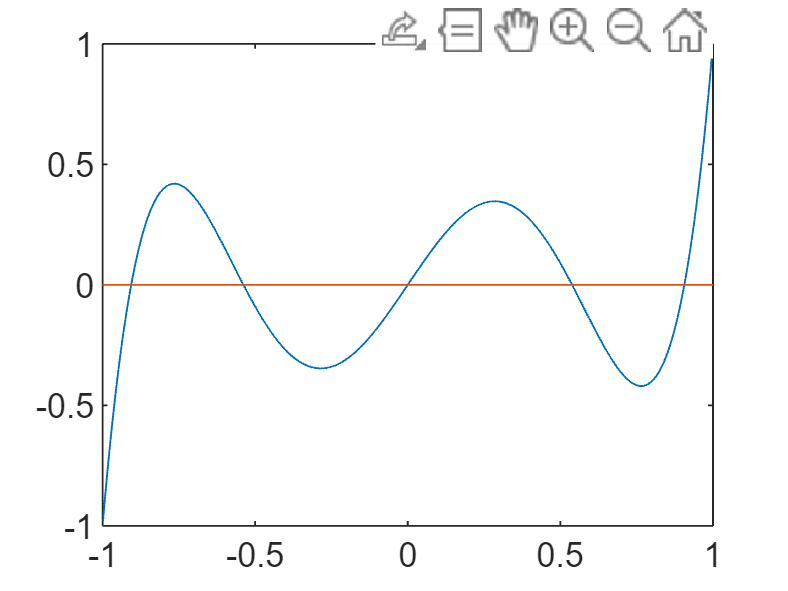

% Define the Legendre polynomial function L5(x)
L5 = @(x) (63*x.^5 - 70*x.^3 + 15*x) / 8;

% Define the derivative of L5(x) for Newton's method
dL5 = @(x) (315*x.^4 - 210*x.^2 + 15) / 8;

% Plot
x = linspace(-1, 1, 1000);
plot(x, L5(x), x, zeros(size(x)));


% Intervals for bisection, based on the image of function
intervals = [-1, -0.7, -0.2, 0.2, 0.7, 1];

% Use bisection method to find a rough approximation of zeros
approx_zeros = zeros(1, 5);
for i = 1:5
    approx_zeros(i) = bisection(L5, intervals(i), intervals(i+1), 1e-5);
end

% Refine zeros using Newton's method
zeros_L5 = zeros(1, 5);
for i = 1:5
    zeros_L5(i) = newton(L5, dL5, approx_zeros(i), 1e-10);
end
    
% Display the zeros of the polynomial
disp('The zeros of the polynomial are:');

The zeros of the polynomial are:


disp(zeros_L5);

   -0.9062   -0.5385         0    0.5385    0.9062



function root = bisection(f, a, b, tol)
% Bisection method to find initial approximations of zeros
    if f(a) * f(b) >= 0
        error('f(a)f(b)<0 not satisfied!') % ensures the root is bracketed
    end
    
    while (b - a) / 2 > tol
        c = (a + b) / 2;
        if f(c) == 0
            break;
        end
        if f(a) * f(c) < 0
            b = c;
        else
            a = c;
        end
    end
    root = (a + b) / 2;
end

function root = newton(f, df, x0, tol)
% Newton's method to refine the approximation
    x = x0;
    while abs(f(x)) > tol
        x = x - f(x) / df(x);
    end
    root = x;
end